# start

clear;  
close all;

addpath("./vlfeat/toolbox");
addpath("./data");
addpath("./data/uav");
addpath("./functions");

vl_setup;

## **make putative matches**

PairNum = 15;
Prefix = "pair";
Postfix_1 = "_A.JPG";
Postfix_2 = "_B.JPG";
Postfix_3 = ".mat";

InlierRatio = zeros(1,PairNum);

 i = 16

i = 16

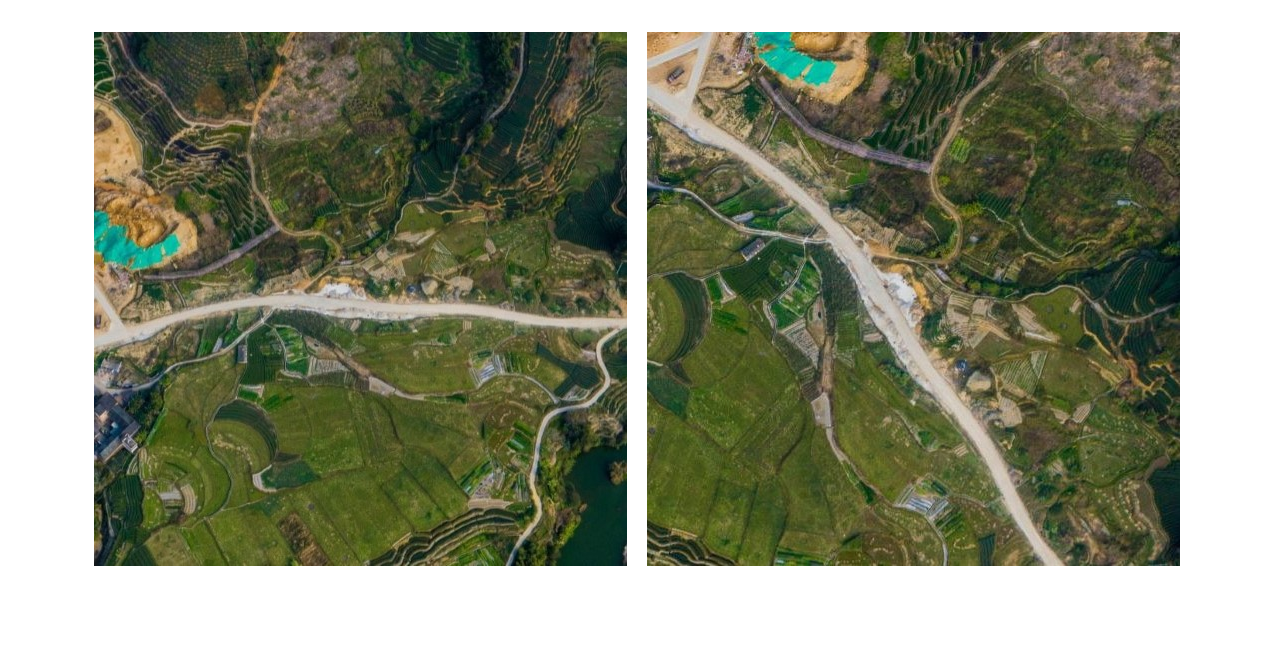

    ImageName_1 = strcat(Prefix, int2str(i), Postfix_1);
    ImageName_2 = strcat(Prefix, int2str(i), Postfix_2);
    Image_1 = imread(ImageName_1);
    Image_2 = imread(ImageName_2);

    [~, P1, P2] = getMatch(Image_1, Image_2);
    CorrectIndex = mvWrongIndex(Image_1, Image_2, P1, P2 ,100, 50);

    r = double(size(CorrectIndex,2))/double(size(P1,2))

r = 0.8687

    InlierRatio(i) = r;
    
    CorrectIndex = CorrectIndex';
    P1 = P1';
    P2 = P2';
    DataFile = strcat("./data/",Prefix,int2str(i),Postfix_3);
    save(DataFile,'CorrectIndex','P1','P2','r');



    